# MATLAB tutoriala: erroen kalkuluak programatzeko erremintak

**Autorea: **Jon Asier Bárcena

Tutorial honetan ikusiko ditugu erroen kalkuluan (eta beste hainbat egoeratan) balio dizkiguten Matlaben komandoak. Gainera, Matlabeko funtzio lokalek irteera bat baino gehiago izan ditzakeela ere ikusiko dugu. 

clear all

## 1-Funtzio anonimoak

Matlaben posible da funtzio sinpleak (besteak beste, **while**, **for** edo **if** gabe), bereziki eragiketa azkarrak egitean datzana, modu azkar batean definitzea. Horretarako, [funtzio anonimo](https://es.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html?s_tid=mwa_osa_a) deritzogun hurrengo egitura erabili behar da:

fizena= @(aldagaiak) esprezioa;

Adibidez:

p=@(x) x.^3-5;
q=@(x) exp(x)-3*cos(x);

Polinomioan **.^** eta **.*** jarri dugu irudia bektore bat izatekotan, kalkuluak gaiz gai egin ditzan. 

Funtzio horiek erabiltzeko kodea konpilatu behar da, eta behin konpilatuta erabili daiteke. Komando leiatilean ere defini daitezke. 

## 2-Funtzio anonimoen grafikoa

Matlaben funtzio anonimoen grafikoak erraz irudika daitezke, **fplot** erabiliz. 

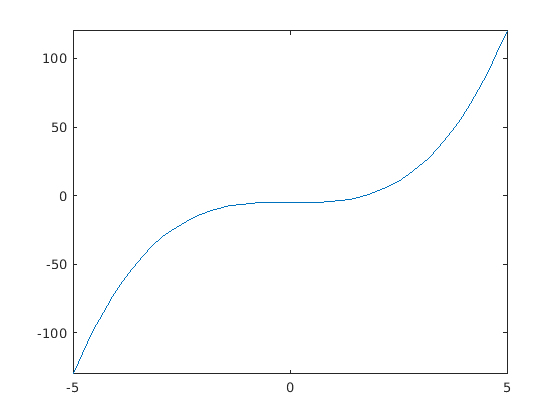

fplot(p)

figure %Grafikoa hona arte nola dagoen ikusteko. 
fplot(p)

Matlabek, defektuz, ez badiogu ezer esaten, $[-5,5]$ tartean egingo dizu grafoa. Tartea aldatzeko, nahikoa da **xlim** erabiltzea. Adibidez, erroaren inguruan zentratuko dugu:

xlim([1 2])

Bide batez, komandoa **xlim **da, nahiz eta zuk zure aldagaiari $y$, $t$, edo beste izen bat jarriz. 

Gainera, izenburua ere gehi daiteke **title **komandoa erabiliz. Gainera, Matlabek ahalbidetzen du Latexeko sintaxia erabiltzea:

title("$p(x)=x^3-5$","Interpreter","latex")

Latexeko sintaxia zein den ez badakizu ez da larria; izan ere, title erabil daiteke interpreterik gabe, ohiko testu bezala. Horretako, nahikoa da title(izenburua) idaztea, non izenburua testu kate bat den. Kendu hurrengo lerroan portzentajea ikusi nahi baduzu nola funtzionatzen duen: 

%title("p(x)=x^3+5") 

Era berean, ardatzen izenak jar daitezke, **xlabel** eta **ylabel** erabiliz. Aurrekoan bezala berdin da nola deitu duzun zure funzioa edo aldagaiari. Horregatik ez da **plabel**, adibidez. Aurrekoan bezala, Latexekin intergreta daiteke, baina hori autazkoa da:

xlabel("x") %Ikusi nola Latex gabe ez duela kurtsiban idazten. 
xlabel("$x$","Interpreter","latex")
ylabel("p(x)","Interpreter","latex") 

Azkenik, lauki-sare (kuadrikula) gehitu al zaio grafikoari:

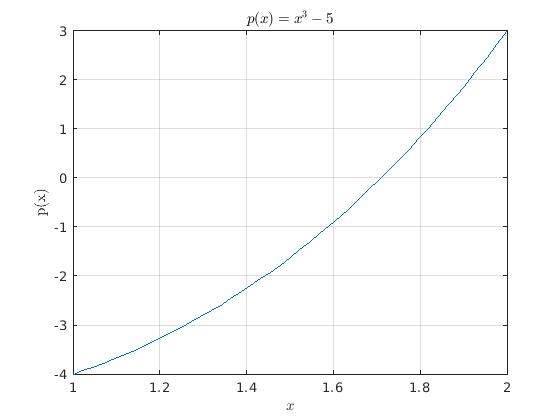

grid on

Azkenik, ohartu grafikoan klikatuz gero zoom egin dezakezula, adibidez $p(x)=0$berdintzaren hurbilpen bat lortzeko. 

## 3-Error komandoa

Funtzioak definitzeko orduan batuzetan esan nahi diogu erabiltzaileari zeozer egin duela txarto, eta konpilazioa gelditzeko. Horretarako, **error **komandoa erabili behar da. Normalean konbinatzen da baldintza batekin. Adibidez, lehen gaian definitutako faktoriala funtzioa hobeto definituko dugu error erabiliz. Kendu portzentajea ikusteko nola funtzioanatzen duen: 

%faktoriala(5.5)
faktoriala(8)

ans = 40320

%faktoriala("Kaixo")

## 4-Funtzio anonimoak eta funtzio lokalak

Posible da Matlaben funtzio lokal baten irudia funtzio anonimo bat izatea. Hori garrantzitsua da zenbakizko metodoetan; izan ere, metodoetan, sarreren artean funtzio bat edo gehiago egoten ohi da; adibidez, bisekzioan, Newton-Raphson-en metodoan, etc. Ikus dezagun konposizio funtzioa adibide bezala:

a=@(x) 2*x+4;
b=@(x) x^2-2;
konposizio(a,b,3)

ans = 18

## 5-Funtzioen irteerak Matlaben

Matlaben posible da funtzioek irteera bat baino gehiago izatea. Horretarako ikus dezagun multieragiketa funtzioa. Argi ikusten da funtzio bat irteera bat baino gehiago izateko, nahikoa dela kortzeteak erabiltzea. Ebalua dezagun funtzioa:

multieragiketa(4,3)

ans = 7

Argi dago aldagai bat itzuli digula soilik, batuketa alegia. Arrazoia da Matlaben irteerako aldagai guztiak ez dutela garrantzi berbera, badago bat, **aldagai nagusia**, eta besteak, **informazio gehigarria**. Matlabek, defektuz, ez badiogu ezer esaten, aldagai nagusia itzuliko digu. Informazio gehigarria izateko, funtzioa deitu behar da esleipen batean, eta irteera kopuru aldagai deitu behar ditugu.

[bat,ken,bid,zat]=multieragiketa(4,3)

bat = 7

ken = 1

bid = 12

zat = 1.3333

Azkenik, ohartu aldagai gutxiago deituz gero, definituta dauden ordenean ezkerretik eskuinera itzuliko dizikizula. 

[bat2, ken2]=multieragiketa(4,3)

bat2 = 7

ken2 = 1

## 6-Funtzioak

### 6.1-Faktoriala funtzioa

Hemen, faktoriala funtzioa definituko dugu, sarrera ezegokia izatekotan errore bat ematen duena. Funtzio hau 3. atalarekin erlazionatuta dago. 

function s=faktoriala(n)
%Funtzio honek n-ren faktoriala kalkulatzen du. Suposatzen dugu n zenbaki
%oso positiboa dela. Bestela errorea emango du. 
if ~isreal(n)%Ez bada zenbaki errela
    error("Sarrera zenbaki bat izan behar da.")
end
if n~=floor(n)%Ez bada zenbaki osoa
    error("Erabili gamma funtzioa. Barkatu eragozpenak.")
end
s=1; 
for i=2:n
s=s*i;%Funtzioetan puntu eta koma idaztea gomendagarria da, irteerak luzeegiak ez izateko. 
end
end  

### 6.2-Konposizio funtzioa. 

Hemen, konposizio funtzioa definituko dugu. Funtzio hau 4. atalean erabiltzen da. 

function  s=konposizio(f,g,x)
%Hemen sarrera f eta g funtzio erreal anonimo dira, eta x erreal bat.
%Irteera f(g(x)) da.
s=f(g(x));
end

### 6.3-Multieragiketa funtzioa

Hemen, multieragiteka funtzioa definituko dugu. Funtzio hau 5. atalean erabiltzen da. 

function [batuketa, kenketa,biderketa,zatiketa]= multieragiketa(a,b)
batuketa=a+b;
kenketa=a-b;
biderketa=a*b;
zatiketa=a/b;
end